cap = interdigitalCapacitor;

cap.NumFingers = 30;
cap.FingerLength = 1500e-6;
cap.FingerWidth = 15e-6;
cap.FingerSpacing = 7.5e-6;
cap.FingerEdgeGap = 10e-6;
cap.Substrate = dielectric(Name="Al2O3", EpsilonR=9.8, LossTangent=0.0003, Thickness=10e-6);
cap.Conductor = metal(Name="Cr", Conductivity=7.9e6, Thickness=100e-9);
cap.PortLineLength = 600e-6;
cap.PortLineWidth = 500e-6;
cap.TerminalStripWidth = 50e-6;
cap

cap =   interdigitalCapacitor with properties:

            NumFingers: 30
          FingerLength: 0.0015
           FingerWidth: 1.5000e-05
         FingerSpacing: 7.5000e-06
         FingerEdgeGap: 1.0000e-05
    TerminalStripWidth: 5.0000e-05
         PortLineWidth: 5.0000e-04
        PortLineLength: 6.0000e-04
                Height: 7.8700e-04
      GroundPlaneWidth: 0.0030
             Substrate: [1×1 dielectric]
             Conductor: [1×1 metal]
            IsShielded: 0


show(cap)
xlim = 0.9

xlim = 0.9000

ylim = 0.5

ylim = 0.5000

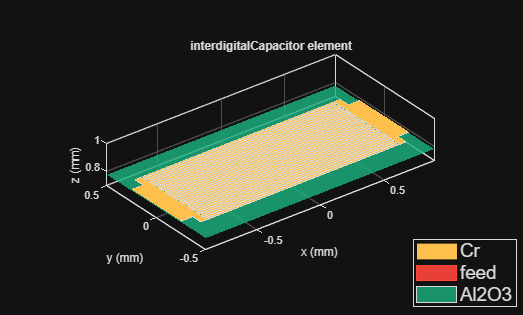

axis([-xlim xlim -ylim ylim 0.7 1])
lgd = findobj(gcf, 'Type', 'Legend');
lgd.FontSize = 14;         % make the text bigger

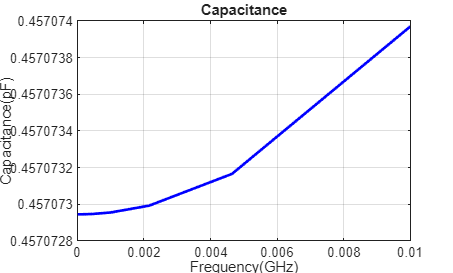

capacitance(cap, logspace(4, 7, 10))

R_target = 10e3;
width = 5e-6;
resistivity = 1.3e-7;
L = (R_target * width * 100e-9) / resistivity

L = 0.0385

Error using interdigitalCapacitor/meshGenerator (line 343)
The value specified for PortLineLength must be greater than 0.0005.

Error in em.MeshGeometry/updateMesh

Error in em.MeshGeometry/getMesh

Error in em.EmStructures/analyze

Error in em.SharedPortAnalysis/protectedsparameters

Error in rfpcb.PortAnalysis/sparameters (